% code for plot results of Widefield imaging, which contain functions listed
% below
% Align neural activity of different trails by behavior events
% plot aligned neural activity of each trial (line + heatmap)
% plot activity correlation of each brain region
% plot neural activity sequence averaged by specific timebin
% plot neural activity averaged by specific behavior
% cut and align the neural activity based on task event written by NY
clear all;
close all;
clc;

% cut and align the neural activity based on task event written by NY
Animal = {'tph314','tph314','tph314','tph314','tph314','tph314'}; %{'tph189','tph199','tph209','tph218','tph228'};
Date = {'20240410','20240412','20240413','20240414','20240415','20240416'}; %{'20230421','20230530','20230817','20230817','20230817'};
totalTrial = 150;
Key = {'roving','roving','roving','roving','roving','roving'}; %{'light90','light90','light90h','light90h','light90h'};
cellset_num = {0,1,2,3,4,5}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
categorize = 'layer'; %'depth'; % categorize neurons by 'layer' or 'depth'
layer_bounds_um = {[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451]}; %[left, center,right] of the
%     Inscopix imaging FOV 
Kota_alignment = 1; %0: do not use, 1:use
% Define the folder where the CSV files are located
pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/tph314_roving/tph314_all_baselines/output';
% need to be fixed because reverse pattern is different between tph189 and tph199
image_reverse = {2,2,2,2,2,2}; %{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/240605/']; %['/home/naohiro/Desktop/Doya_rotation/analysis/output/230913/imaging_multi/'];

% plot event triggered neural activity
force_thr = 50; 
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 4:z scored by compared trials

data_folders = cell(1,length(Animal));
% data_folders = [];
acc_neural_activity_data = cell(1,length(Animal));
acc_neural_property_data = cell(1,length(Animal));
% correspondences_table = cell(length(Animal));
for i = 1:length(Animal)
    % if i <=2 %temporal operation
    %    data_folders(i) = {['/media/naohiro/ADATA HV620S/Doya_rotation' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % else
    %     data_folders(i) = {['/media/naohiro/ADATA HV620S/Doya_rotation/202308' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % end
    data_folders(i) = {['/media/naohiro/SSD-SCTU3A/Nao_behavior/202403' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);    
    neural_activity_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces.csv'],'NumHeaderLines',0);
    neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
    neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces-props.csv']);
    neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
    if contains(Key,'roving')
        all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
        correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_roving_0.5.csv']);
    elseif contains(Key,'switching')
        all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_switching-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
        correspondences_table = readtable([strjoin(data_folder(i)) filesep 'correspondences_table_switching_0.5.csv']);         
    else
        all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
        correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_ordinary_0.5.csv']);
    end
    cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==int32(cell2mat(cellset_num(i))),:);
    %%% have to return the line below %%%
    global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
    % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
    local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
    acc_neural_activity_data{i} = neural_activity_data(:,local_acc_idx+1);
    acc_neural_property_data{i} = neural_property_data(local_acc_idx+1,:);
    %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    %     data(i,:) = behavior_sequence_fps;
    % save table as mat file %%%have to change!variable names are different
    % save([strjoin(data_folders(i)) filesep Animal(i) '_neural_activity_' Date(i) '_' Key(i) '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');    
end

% % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% % neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
% % acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% % acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))

ans = 0

strcmp(neural_property_table(:,'Status'),'accepted')

ans = logical
   0


acc_neural_activity_data{1}

ans =    -0.6073   19.1943    5.5771    8.0588   18.8480    1.5843    6.6685   11.2127   15.5964    4.0139    7.7331   12.0224    9.3085   12.8836    4.6028   -0.1951    1.3802    8.1680    1.9024   21.4889    6.0130    4.4076   12.9727   12.5856   -0.7828    5.7557   13.7775    4.7270   16.2622    9.0165    8.5863    8.8753   11.0956    3.5341    9.1557   24.6044    8.5480    3.4610    2.8019   20.2078    4.8963    2.9867   -2.6520    8.7551    2.9049   11.1704   -0.3836   10.1542   12.8086   33.1316
    1.6376   19.8500    4.5161   13.0247   19.3320    1.2328    2.4648   14.5876   18.3129    4.8154    6.1913   12.0239    9.7267   18.3657    5.7911    1.7272    1.5831    9.3582    1.6876   19.5154   11.8173    1.7287   12.8809   10.0625    0.1223    4.3321   14.3230    3.9321   15.7335   10.9659   11.1277    9.2194   11.2593    2.8302    8.4217   20.8808    7.0851    5.3927    2.5820   21.4564    5.2198    5.3609   -2.6728    6.2857    4.0007   12.6060    0.2426   12.1575   15.3651   

acc_neural_property_data{1}

ans =   255.0000  255.0000  255.0000  125.0000   24.0000    1.0000    8.9443    1.0000
  255.0000  255.0000  255.0000   78.0000   36.0000    1.0000    9.0554    1.0000
  255.0000  255.0000  255.0000  120.0000   33.0000    1.0000    9.0554    1.0000
  255.0000  255.0000  255.0000  113.0000   20.0000    1.0000    8.5440    1.0000
  255.0000  255.0000  255.0000   72.0000   15.0000    1.0000    9.4340    1.0000
  255.0000  255.0000  255.0000  124.0000   49.0000    1.0000    8.5440    1.0000
  255.0000  255.0000  255.0000  109.0000   38.0000    1.0000   10.1980    1.0000
  255.0000  255.0000  255.0000  126.0000   16.0000    1.0000    9.4868    1.0000
  255.0000  255.0000  255.0000  116.0000   19.0000    1.0000    8.6023    1.0000
  255.0000  255.0000  255.0000   93.0000   24.0000    1.0000    9.0554    1.0000


if Kota_alignment == 1    
    % Get a list of all CSV files in the folder
    csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
    
    % Initialize an empty cell array to store the matrices
    AlinmentTimingCells = {};
    
    % Loop through each CSV file and read the data
    for k = 1:length(csvFiles)
        % Get the full file name and read the CSV file
        fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
        data = table2array(readtable(fileName));
        
        % Store the data in the cell array
        AlinmentTimingCells{k} = data;
    end
end

% % plot neural activity
% % addpath([working_directory 'PCA_and_ICA\Subaxis']);
% ylimit=[0 50];
% mean_acc_neural_activity = mean(acc_neural_activity_data,2);
% figure
% % for i = 1:size(acc_neural_activity_data,2)
% %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%     for j = 1:size(acc_neural_activity_data,2)
%         hold on 
%         r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
%         hold off
%     end
%     alpha(r,0.1);
%     hold on
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     ylabel('neural activity');
%     xlabel('time (sec)')
% 
% % end
% % saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

% plot neural activity heatmap
addpath([working_directory 'Utility' filesep 'Subaxis']);
climit = [0 50]

climit =      0    50


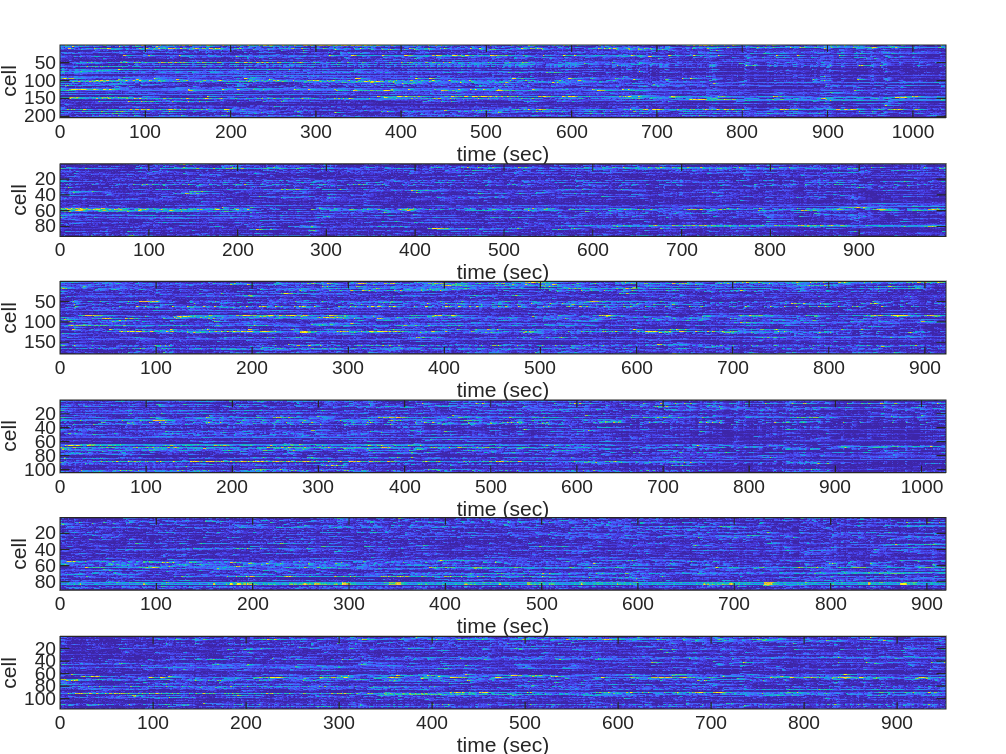

figure
set(gcf,'color','w');
for i = 1:length(Animal) 
    subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
    clims = climit;
    image = transpose(acc_neural_activity_data{i});
%     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
    imagesc(0:0.1:(size(acc_neural_activity_data{i},1)-1)/10,1:size(acc_neural_activity_data{i},2),image,clims);
%     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
end

filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_all_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

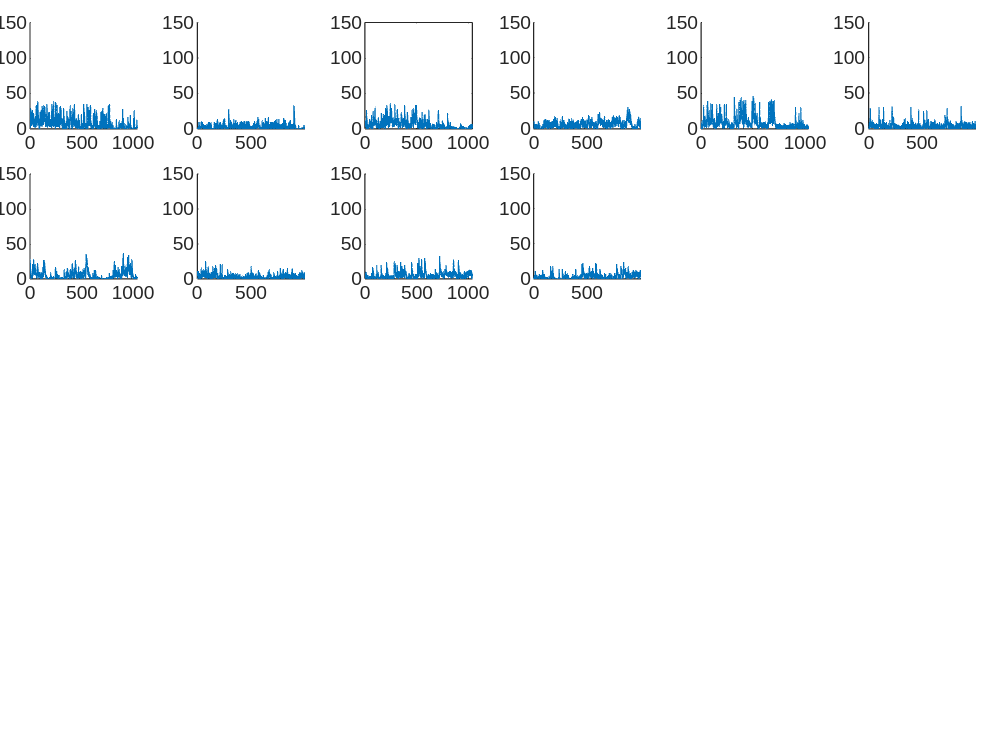

addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 10; %113;
ylimit=[0 150];
figure
for j = 1:length(Animal)
    for i = 1:example_num
        subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        b = plot(0:0.1:(size(acc_neural_activity_data{j},1)-1)/10,acc_neural_activity_data{j}(:,display_start+i));
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim(ylimit); 
        xlim([0 (size(acc_neural_activity_data{j},1)-1)/10]);
        xlabel('');
        ylabel('');
%         axis off;
        box off;
    %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end
end

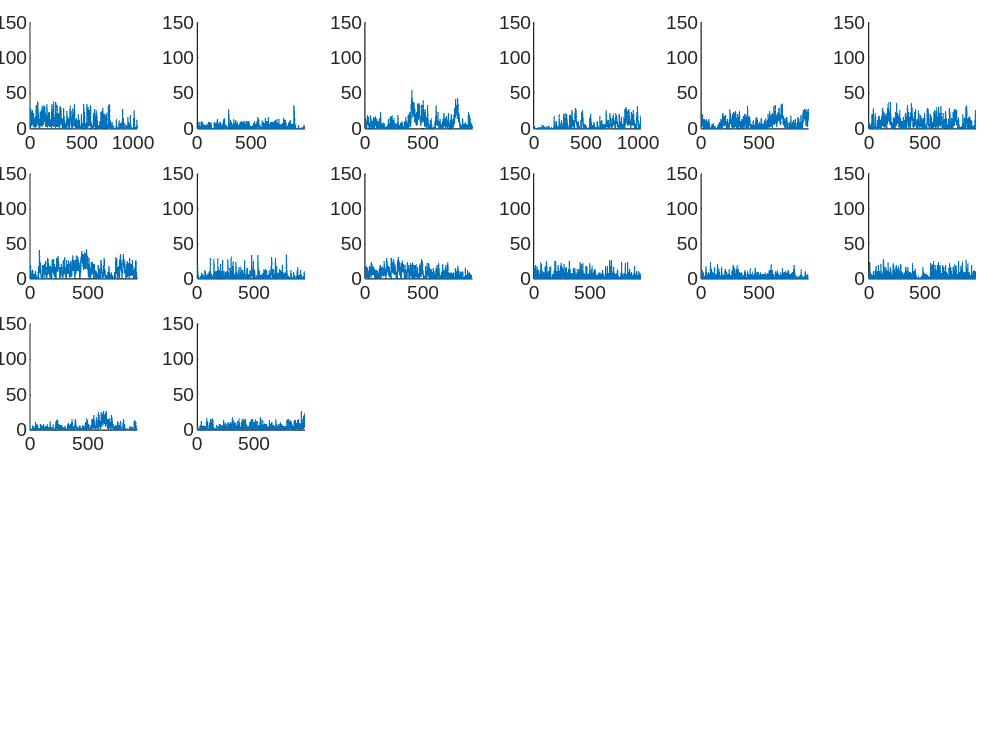

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_exmple_activity_traces.png'];
saveas(gcf,filename);

0:0.1:(size(acc_neural_activity_data,2)-1)/10

ans =          0    0.1000    0.2000    0.3000    0.4000    0.5000


% % plot event triggered neural activity
% force_thr = 50;
% position_thr = 10;
% fps = 10;
% before_event = 2; %1;
% after_event  = 4; %2;
% norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell
% 
% % for i = 1:length(Animal)
% %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(j)) '.mat']);
% % end

% j=1;
% load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% var_list = who('-file' ,[strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% % var_list = who -file /media/naohiro/ADATA HV620S/Doya_rotation/202308/20230819_tph228_heavy90h/tph228_behavior_20230819_heavy90h.mat
% disp(var_list);

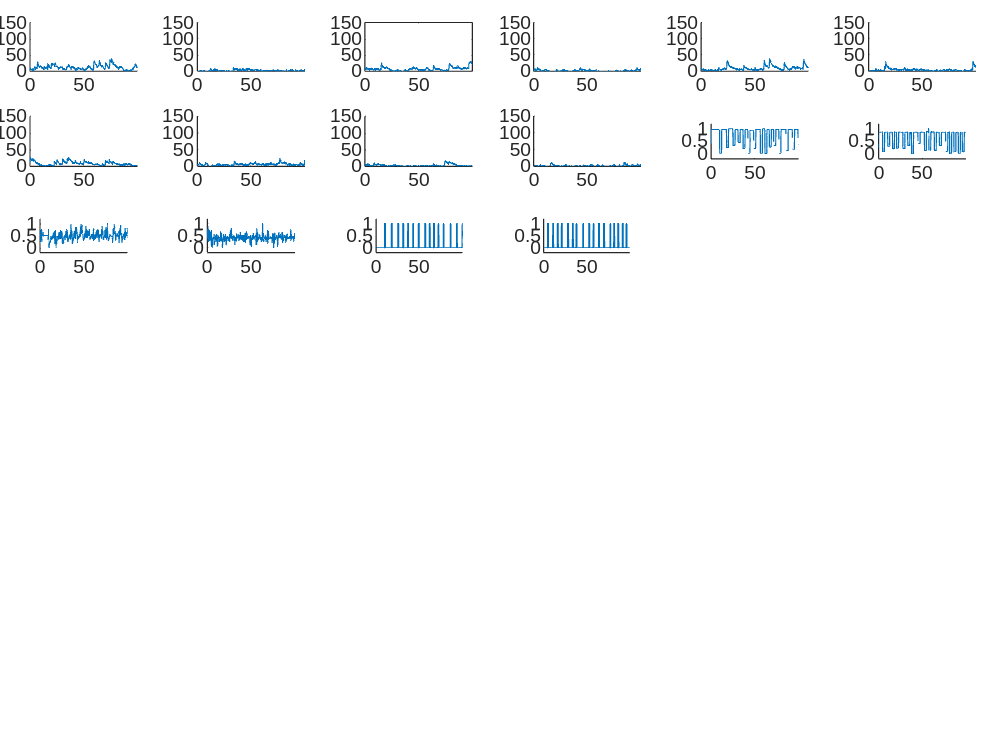

% plot example neural activity with behaviors
addpath([working_directory 'Utility' filesep 'Subaxis']);
example_num = 5;
display_start = 10; %113;
ylimit=[0 150];
range_max =1000;
figure
for j = 1:length(Animal)
    load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
    for i = 1:example_num
        subaxis(example_num+3,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        b = plot(0:0.1:(range_max-1)/10,acc_neural_activity_data{j}(1:range_max,display_start+i));
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim(ylimit); 
        xlim([0 (range_max-1)/10]);
        xlabel('');
        ylabel('');
%         axis off;
        box off;
        %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end

    for i = 1:3
        subaxis(example_num+3,length(Animal),2*(i+example_num)+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
        normalized_behavior = normalize_rows(transpose(behavior_neural_time(1:range_max,5+i)));
        b = plot(0:0.1:(range_max-1)/10,normalized_behavior);
    %     title([brain_roi_name(i)], 'FontSize',6);
        ylim([-0.2 1.2]); 
        xlim([0 (range_max-1)/10]);
        xlabel('');
        ylabel('');
%         axis off;
        box off;
    %     ylabel('neural activity');
    %     xlabel('time (sec)')
    end
end

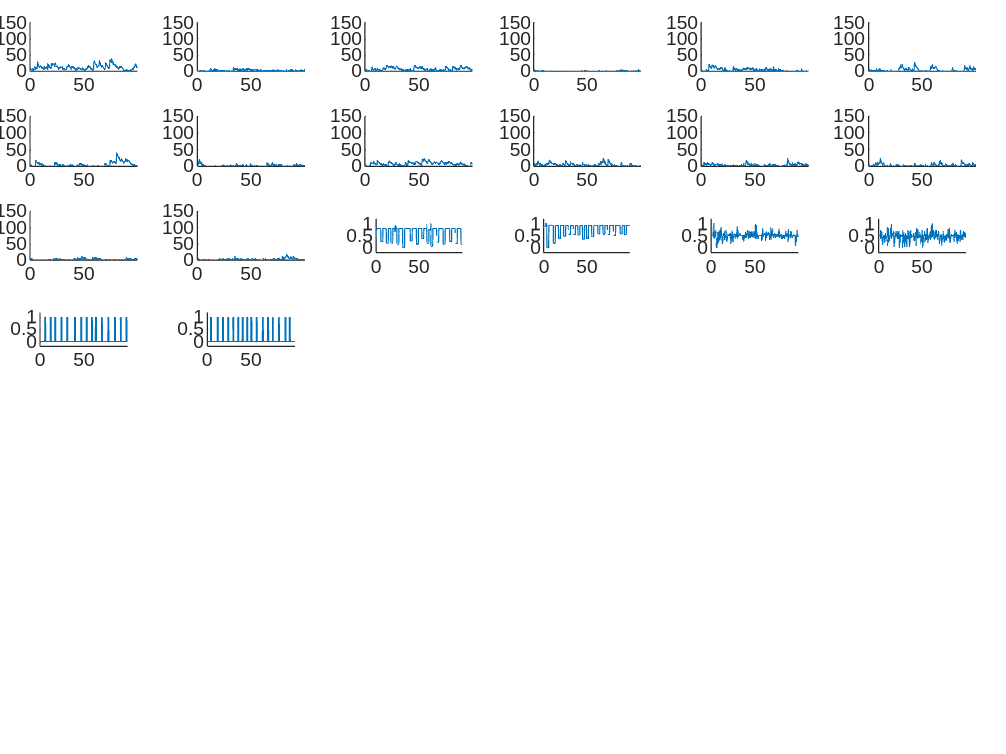

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_exmple_activity_behavior_traces.png'];
saveas(gcf,filename);

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
depth = cell(1,length(Animal));
if categorize == 'depth'
    for i = 1:length(Animal)        
        if image_reverse{i} == 0
            depth{i} = 1050 - acc_neural_property_data{i}(:,4)*1050/(1280/4);    %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        elseif image_reverse{i} == 2
            depth = 1050 - acc_neural_property_data{i}(:,4)*1050/(1280/4); 
        else
            depth{i} = acc_neural_property_data{i}(:,4)*1050/(1280/4);
    %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        end
    end
    depth_conc = depth{1};
    for i_animal = 2:length(Animal)
        depth_conc = vertcat(depth_conc, depth{i_animal});
    end
end

% determine which layer each cell belong by cell position
if categorize == 'layer'
    pointAreas = cell(1,length(Animal));
    for i = 1:length(Animal)
    %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
    %     Inscopix imaging FOV
        layer_bounds_pix = layer_bounds_um{i} * (1280/4) /1050; 
        layer_bounds_len = length(layer_bounds_pix);
        x_pix = linspace(1, 200, layer_bounds_len);
        % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
        % TODO: have to be reverse y axis and x axis depending on the orientation of
        % the image
        if image_reverse{i} == 0
            neural_locations = [acc_neural_property_data{i}(:,5), acc_neural_property_data{i}(:,4)];
        elseif image_reverse{i} == 2
            neural_locations = [800/4 - acc_neural_property_data{i}(:,5), 1280/4 - acc_neural_property_data{i}(:,4)];        
        else
            % reverse layer_bounds_pix
            layer_bounds_pix = flip(layer_bounds_pix)
            neural_locations = [1280/4 - acc_neural_property_data{i}(:,5), acc_neural_property_data{i}(:,4)];       
        end
        %reshape neural_locations to N*2
        % combine x_pix and layer_bounds_pix to 3*2
        linePoints = [x_pix(:), layer_bounds_pix(:)];
        % determine the layer each cell belong based on the matlab function
        % 0: layer2/3, 1: layer5
        pointAreas{i} = classifyPoints(neural_locations, linePoints);
        % save table as mat file %%%have to change!variable names are different
        % save([strjoin(data_folders(i)) filesep Animal(i) '_neural_activity_' Date(i) '_' Key(i) '.mat'], 'pointAreas', '-append');     
    end
    pointAreas_conc = pointAreas{1};
    for i_animal = 2:length(Animal)
        pointAreas_conc = vertcat(pointAreas_conc, pointAreas{i_animal});
    end 
end

trial_start_act_multi_animals = cell(1,length(Animal));
trial_end_act_multi_animals   = cell(1,length(Animal));
position_act_multi_animals    = cell(1,length(Animal));
force_act_multi_animals       = cell(1,length(Animal));
reward_act_multi_animals      = cell(1,length(Animal));
trial_start_act_raw_multi_animals = cell(1,length(Animal));
trial_end_act_raw_multi_animals   = cell(1,length(Animal));
position_act_raw_multi_animals    = cell(1,length(Animal));
force_act_raw_multi_animals       = cell(1,length(Animal));
reward_act_raw_multi_animals      = cell(1,length(Animal));
start_I    = cell(1,length(Animal));
end_I      = cell(1,length(Animal));
position_I = cell(1,length(Animal));
force_I    = cell(1,length(Animal));
reward_I   = cell(1,length(Animal));
trial_start_act_max_act_times = cell(1,length(Animal));
trial_end_act_max_act_times   = cell(1,length(Animal));
position_act_max_act_times    = cell(1,length(Animal));
force_act_max_act_times       = cell(1,length(Animal));
reward_act_max_act_times      = cell(1,length(Animal));
for i_animal = 1:length(Animal)
    load([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_behavior_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat']);
    % 'behavior_neural_time'
    trial_start = behavior_neural_time(:,3);
    trial_end   = behavior_neural_time(:,4);
    position    = behavior_neural_time(:,6);
    force       = behavior_neural_time(:,7);
    reward      = behavior_neural_time(:,8);
    % find index of each event
    trial_start_idx = find(trial_start == 1);
    trial_end_idx   = find(trial_end == 1);
    force_idx       = find(force > force_thr);
    reward_idx      = find(reward == 1); 
    position_diff   = diff(position);
    position_idx    = find(position_diff > position_thr);
    % idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
    % event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
    trial_start_act = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    trial_end_act   = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    position_act    = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    force_act       = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    reward_act      = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    sig_cell_idxs   = cell(0,5);
    
    % only count first idx in 1 second
    temp_position_idx = position_idx(1);
    for i = 2:length(position_idx)
        if position_idx(i) - temp_position_idx(end) >= fps
            temp_position_idx(end+1) = position_idx(i);
        end
    end
    position_idx = temp_position_idx;
    
    temp_force_idx = force_idx(1);
    for i = 2:length(force_idx)
        if force_idx(i) - temp_force_idx(end) >= fps
            temp_force_idx(end+1) = force_idx(i);
        end
    end
    force_idx = temp_force_idx;
    
    temp_reward_idx = reward_idx(1);
    for i = 2:length(reward_idx)
        if reward_idx(i) - temp_reward_idx(end) >= fps
            temp_reward_idx(end+1) = reward_idx(i);
        end
    end
    reward_idx = temp_reward_idx;
    
    % for i = 1:size(idxs,2)
    %     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
    exception_count = 0;
    trial_start_acts = {};
    for j = 1:length(trial_start_idx)
        if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_start_act = trial_start_act+transpose(acc_neural_activity_data{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
            trial_start_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:));
        end
    end
    trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
    trial_start_acts = reshape(cell2mat(trial_start_acts),[size(acc_neural_activity_data{i_animal}, 2) size(trial_start_act,2) length(trial_start_idx)-exception_count]); %[191 31 147]);
    if norm == 1
        trial_start_act = normalize_rows(trial_start_act);
    elseif norm ==2 || norm ==4
           trial_start_act = zscore_rows(trial_start_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(trial_start_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_start_acts = trial_start_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_start_acts(i_cell,:)),squeeze(max_trial_start_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{1} = sig_cell_idx;
        end
        trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
    end
    trial_start_act_raw = trial_start_act;
    [M,start_I{i_animal}] = max(trial_start_act,[],2);
    trial_start_act = cat(2,start_I{i_animal},trial_start_act);
    trial_start_act = sortrows(trial_start_act);
    trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
    trial_start_act(:,1) = [];
    
    exception_count = 0;
    trial_end_acts = {};
    for j = 1:length(trial_end_idx)
        if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_end_act = trial_end_act+transpose(acc_neural_activity_data{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
            trial_end_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:));
        end
    end
    trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
    trial_end_acts = reshape(cell2mat(trial_end_acts),[size(acc_neural_activity_data{i_animal}, 2) size(trial_end_act,2) length(trial_end_idx)-exception_count]);
    if norm == 1
        trial_end_act = normalize_rows(trial_end_act);
    elseif norm ==2
       trial_end_act = zscore_rows(trial_end_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(trial_end_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_end_acts = trial_end_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_end_acts(i_cell,:)),squeeze(max_trial_end_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{2} = sig_cell_idx;
        end
        trial_end_act = zscore_rows(trial_end_act(find(sig_cell_idx==1),:));
    end
    trial_end_act_raw = trial_end_act;
    [M,end_I{i_animal}] = max(trial_end_act,[],2);
    trial_end_act = cat(2,end_I{i_animal},trial_end_act);
    trial_end_act = sortrows(trial_end_act);
    trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
    trial_end_act(:,1) = [];
    
    exception_count = 0;
    position_acts = {};
    for j = 1:length(position_idx)
        if position_idx(j)-fps*before_event<=0 | position_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            position_act = position_act+transpose(acc_neural_activity_data{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:)); 
            position_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:));
        end
    end
    position_act = position_act/(length(force_idx)-exception_count);
    position_acts = reshape(cell2mat(position_acts),[size(acc_neural_activity_data{i_animal}, 2) size(position_act,2) length(position_idx)-exception_count]);
    if norm == 1
        position_act = normalize_rows(position_act);
    elseif norm ==2
           position_act = zscore_rows(position_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(position_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_position_acts = position_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(position_acts(i_cell,:)),squeeze(max_position_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{3} = sig_cell_idx;
        end
        position_act = zscore_rows(position_act(find(sig_cell_idx==1),:));
    end
    position_act_raw = position_act;
    [M,pos_I{i_animal}] = max(position_act,[],2);
    position_act = cat(2,pos_I{i_animal},position_act);
    position_act = sortrows(position_act);
    position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
    position_act(:,1) = [];
    
    exception_count = 0;
    force_acts = {};
    for j = 1:length(force_idx)
        if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            force_act = force_act+transpose(acc_neural_activity_data{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
            force_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:));
        end
    end
    force_act = force_act/(length(force_idx)-exception_count);
    force_acts = reshape(cell2mat(force_acts),[size(acc_neural_activity_data{i_animal}, 2) size(force_act,2) length(force_idx)-exception_count]); %-1]);
    if norm == 1
        force_act = normalize_rows(force_act);
    elseif norm ==2
           force_act = zscore_rows(force_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(force_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_force_acts = force_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{4} = sig_cell_idx;
        end
        force_act = zscore_rows(force_act(find(sig_cell_idx==1),:));
    end
    force_act_raw = force_act;
    [M,force_I{i_animal}] = max(force_act,[],2);
    force_act = cat(2,force_I{i_animal},force_act);
    force_act = sortrows(force_act);
    force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
    force_act(:,1) = [];
    
    exception_count = 0;
    reward_acts = {};
    for j = 1:length(reward_idx)
        if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            reward_act = reward_act+transpose(acc_neural_activity_data{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
            reward_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:));
        end
    end
    reward_act = reward_act/(length(reward_idx)-exception_count);
    reward_acts = reshape(cell2mat(reward_acts),[size(acc_neural_activity_data{i_animal}, 2) size(reward_act,2) length(reward_idx)-exception_count]);
    if norm == 1
        reward_act = normalize_rows(reward_act);
    elseif norm ==2
       reward_act = zscore_rows(reward_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(reward_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_reward_acts = reward_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(reward_acts(i_cell,:)),squeeze(max_reward_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{5} = sig_cell_idx;
        end
        reward_act = zscore_rows(reward_act(find(sig_cell_idx==1),:));
        % save table as mat file
        save([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_neural_activity_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat'], 'sig_cell_idxs', '-append');  
    end
    reward_act_raw = reward_act;
    [M,reward_I{i_animal}] = max(reward_act,[],2);
    reward_act = cat(2,reward_I{i_animal},reward_act);
    reward_act = sortrows(reward_act);
    reward_act_max_act_times{i_animal} = reward_act(:,1)/10 -2;
    reward_act(:,1) = [];
    trial_start_act_multi_animals{i_animal} = trial_start_act;
    trial_end_act_multi_animals{i_animal}   = trial_end_act;
    position_act_multi_animals{i_animal}    = position_act;
    force_act_multi_animals{i_animal}       = force_act;
    reward_act_multi_animals{i_animal}      = reward_act;
    trial_start_act_raw_multi_animals{i_animal} = trial_start_act_raw;
    trial_end_act_raw_multi_animals{i_animal}   = trial_end_act_raw;
    position_act_raw_multi_animals{i_animal}    = position_act_raw;
    force_act_raw_multi_animals{i_animal}       = force_act_raw;
    reward_act_raw_multi_animals{i_animal}      = reward_act_raw;

%     if i_animal == 1
%         trial_start_act_multi_animals = trial_start_act;
%         trial_end_act_multi_animals   = trial_end_act;
%         position_act_multi_animals    = positon_act;
%         force_act_multi_animals       = force_act;
%         reward_act_multi_animals      = reward_act;
%     else
%         trial_start_act_multi_animals = [trial_start_act_multi_animals; trial_start_act];
%         trial_end_act_multi_animals   = [trial_end_act_multi_animals; trial_end_act];
%         position_act_multi_animals    = [position_act_multi_animals; positon_act];
%         force_act_multi_animals       = [force_act_multi_animals; force_act];
%         reward_act_multi_animals      = [reward_act_multi_animals; reward_act];        
%     end
end

trial_start_act_conc = trial_start_act_raw_multi_animals{1};
trial_end_act_conc   = trial_end_act_raw_multi_animals{1};
position_act_conc    = position_act_raw_multi_animals{1};
force_act_conc       = force_act_raw_multi_animals{1};
reward_act_conc      = reward_act_raw_multi_animals{1};
trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
position_act_max_act_times_conc    = position_act_max_act_times{1};
force_act_max_act_times_conc       = force_act_max_act_times{1};
reward_act_max_act_times_conc      = reward_act_max_act_times{1};
for i_animal = 2:length(Animal)
    trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_raw_multi_animals{i_animal});
    trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_raw_multi_animals{i_animal});
    position_act_conc = vertcat(position_act_conc, position_act_raw_multi_animals{i_animal});
    force_act_conc = vertcat(force_act_conc, force_act_raw_multi_animals{i_animal});
    reward_act_conc = vertcat(reward_act_conc, reward_act_raw_multi_animals{i_animal});
    trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
    trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
    position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
    force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
    reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
end

% trial_start_act_conc = trial_start_act_multi_animals{1};
% trial_end_act_conc   = trial_end_act_multi_animals{1};
% position_act_conc    = position_act_multi_animals{1};
% force_act_conc       = force_act_multi_animals{1};
% reward_act_conc      = reward_act_multi_animals{1};
% trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
% trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
% position_act_max_act_times_conc    = position_act_max_act_times{1};
% force_act_max_act_times_conc       = force_act_max_act_times{1};
% reward_act_max_act_times_conc      = reward_act_max_act_times{1};
% for i_animal = 2:length(Animal)
%     trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%     trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%     position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%     force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%     reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%     trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
%     trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
%     position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
%     force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
%     reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
% end

% caluculate ETA of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    pull_sig_cell_idxs   = cell(0,length(AlinmentTimingCells));
    pull_actss = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        for k_animal = 1:length(Animal)
            pull_act      = zeros(size(acc_neural_activity_data{k_animal},2),fps*(before_event+after_event)+1);
            exception_count = 0;
            pull_acts = {};
            pull_idx = AlinmentTimingCells{i};
            for j = 1:size(pull_idx,2)
                if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data{k_animal},1)
                    exception_count = exception_count + 1;
                else
                    pull_act = pull_act+transpose(acc_neural_activity_data{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                    pull_acts{end+1}= transpose(acc_neural_activity_data{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
                end
            end
            pull_act = pull_act/(size(pull_idx,2)-exception_count);
            pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
            if norm == 1
                pull_act = normalize_rows(pull_act);
            elseif norm ==2 || norm == 4
               pull_act = zscore_rows(pull_act); 
            elseif norm ==3
                sig_cell_idx = zeros(1,size(acc_neural_activity_data{k_animal}, 2));
                for i_cell = 1:size(acc_neural_activity_data{k_animal}, 2)
                    [~,max_idx] = max(mean(pull_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
                    max_pull_acts = pull_acts(i_cell,max_idx,:);
                    [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(max_pull_acts),'Vartype','unequal');
                    if h == 1
                        sig_cell_idx(i_cell) = 1;
                    else
                        sig_cell_idx(i_cell) = 0;
                    end
                    pull_sig_cell_idxs{i} = sig_cell_idx;
                end
                pull_act = zscore_rows(pull_act(find(sig_cell_idx==1),:));
            end

            if k_animal == 1
                pull_act_multi_animals = pull_act;
            else
                pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
            end            
            [M,pull_I{k_animal}] = max(pull_act,[],2);
            pull_act = cat(2,pull_I{k_animal},pull_act);
            pull_act = sortrows(pull_act);
            pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
            pull_act(:,1) = [];
        end
        pull_actss{i} = pull_act_multi_animals;
        pull_sig_cell_idxs{i} = pull_I;
    end
end

% write eta code by categrizing neurons by layers

if categorize == 'layer'
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    [M,trial_end_i] = max(trial_end_act_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endAreas = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    [M,position_i] = max(position_act_conc,[],2);
    position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_conc);
    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    positionAreas = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    [M,force_i] = max(force_act_conc,[],2);
    force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_conc);
    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceAreas = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    [M,reward_i] = max(reward_act_conc,[],2);
    reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardAreas = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_conc(find(startAreas == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_conc(find(startAreas == 0),:);
    trial_end_act_layer23_conc = trial_end_act_conc(find(endAreas == 1),:);
    trial_end_act_layer5_conc  = trial_end_act_conc(find(endAreas == 0),:);
    position_act_layer23_conc = position_act_conc(find(positionAreas == 1),:);
    position_act_layer5_conc  = position_act_conc(find(positionAreas == 0),:);
    force_act_layer23_conc = force_act_conc(find(forceAreas == 1),:);
    force_act_layer5_conc  = force_act_conc(find(forceAreas == 0),:);
    reward_act_layer23_conc = reward_act_conc(find(rewardAreas == 1),:);
    reward_act_layer5_conc  = reward_act_conc(find(rewardAreas == 0),:);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if categorize == 'layer' & Kota_alignment == 1
    pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullAreass   = cell(0,length(AlinmentTimingCells));
    pull_actss_ordered = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act_multi_animals = pull_actss{i};
    % align concatenated eta neural activities
        [M,pull_i] = max(pull_act_multi_animals,[],2);
        pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_multi_animals);
        pull_act_multi_animals = sortrows(pull_act_multi_animals);
        pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
        pullAreas = pull_act_multi_animals(:,2);
        pull_act_multi_animals(:,1:2) = [];
        pull_actss_ordered{i} = pull_act_multi_animals;

        pull_act_layer23_cells{i} = pull_act_multi_animals(find(pullAreas == 1),:); %% TODO: need to modify
        pull_act_layer5_cells{i}  = pull_act_multi_animals(find(pullAreas == 0),:);
        pullAreass{i} = pullAreas;
    end
end

% write eta code with depth

if categorize == 'depth'
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,depth_conc ,trial_start_act_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startDepth = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    [M,trial_end_i] = max(trial_end_act_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,depth_conc ,trial_end_act_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endDepth = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    [M,position_i] = max(position_act_conc,[],2);
    position_act_conc = cat(2, position_i,depth_conc ,position_act_conc);
    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    posDepth = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    [M,force_i] = max(force_act_conc,[],2);
    force_act_conc = cat(2, force_i,depth_conc ,force_act_conc);
    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceDepth = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    [M,reward_i] = max(reward_act_conc,[],2);
    reward_act_conc = cat(2, reward_i,depth_conc ,reward_act_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardDepth = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if categorize == 'depth' & Kota_alignment == 1
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullDepths   = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act_multi_animals = pull_actss{i};
    % align concatenated eta neural activities
        [M,pull_i] = max(pull_act_multi_animals,[],2);
        pull_act_multi_animals = cat(2, pull_i,depth_conc ,pull_act_multi_animals);
        pull_act_multi_animals = sortrows(pull_act_multi_animals);
        pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
        pullDepth = pull_act_multi_animals(:,2);
        pull_act_multi_animals(:,1:2) = [];
        % 
        % pull_act_layer23_cells{i} = pull_actss{i}(:,find(pullAreas == 1),:); %% TODO: need to modify
        % pull_act_layer5_cells{i}  = pull_actss{i}(:,find(pullAreas == 0),:);
        pullDepths{i} = pullDepth;
    end
end

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2 | norm == 3 | norm == 4
    climit = [-2 2];
% else
%     climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     4.0447    4.0261    3.8988    3.9121    3.7567    3.8498    3.7053    3.6526    3.5345    3.6105    3.5001    3.5074    3.3821    3.2325    3.0398    2.9143    2.8313    2.6980    2.8201    2.9537    3.1022    3.0742    2.8406    3.0626    2.8533    2.9001    2.7735    2.6967    2.6241    2.5915    2.5492    2.4876    2.4474    2.3722    2.5138    2.5849    2.4434    2.3591    2.3299    2.3815    2.5514    2.7066    2.9660    3.0100    3.0958    3.2063    3.3772    3.4783    3.5556    3.6997
   15.3633   15.0036   15.2615   15.2870   15.1794   15.3108   15.1144   15.3055   15.2044   14.8294   14.9475   14.9496   14.7727   14.7062   14.6017   14.5801   14.4633   14.4594   14.4958   14.4010   14.4963   14.3858   14.1293   14.0492   14.0411   14.2792   14.3873   14.4653   14.7261   14.8644   14.9656   14.9816   14.9544   15.0603   15.1568   15.2214   15.2515   15.2086   15.1178   15.2353   15.0493   15.1115   15.1814   15.1530   14.8885   15.1293   15.0427   14.9499   14.7920 

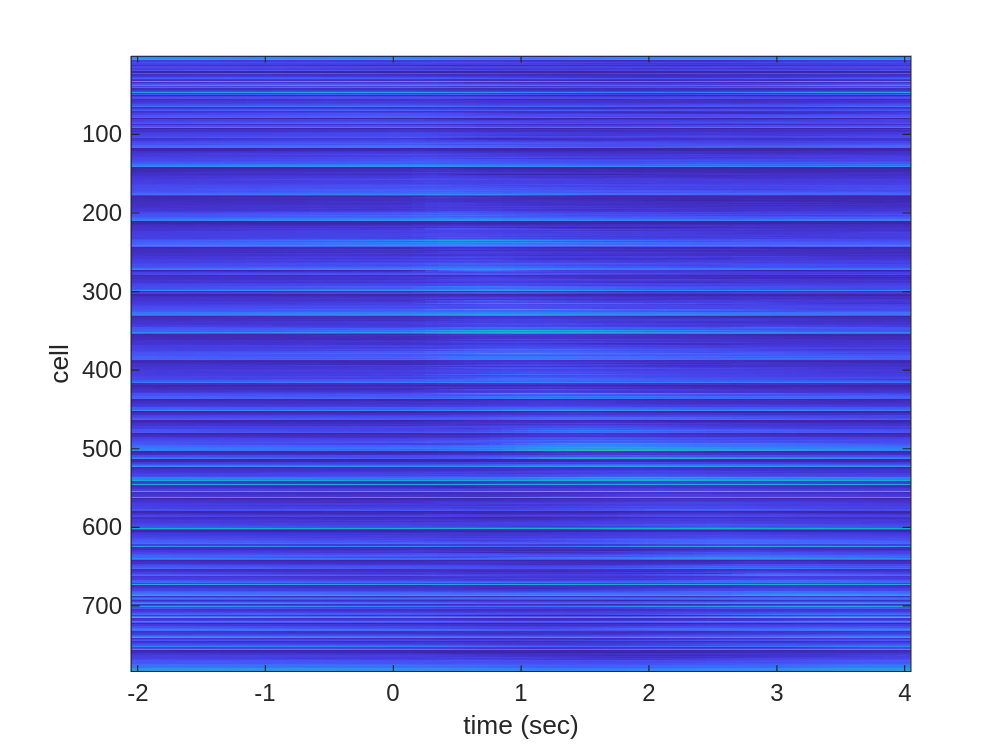

    imagesc(-before_event:0.1:after_event,1:size(trial_start_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_start_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     5.0479    4.7772    4.7766    4.7911    4.7286    4.9215    4.8952    4.9848    4.6825    4.6942    4.8828    4.8812    4.6333    4.6546    4.9733    4.9994    4.7782    4.7090    4.7087    4.7345    4.3934    4.2775    4.0050    4.1079    4.2509    4.2440    4.1676    4.3591    4.2957    4.1658    4.3530    4.2321    4.3310    4.4028    4.4402    4.4045    4.4661    4.6545    4.5575    4.5674    4.5693    4.5693    4.6543    4.3894    4.3897    4.3634    4.7137    4.5982    4.6016    4.5885
   15.5034   15.4372   15.4329   15.2476   15.0682   14.9616   14.9296   14.9342   14.7229   14.8143   14.7315   14.4832   14.7420   14.6332   14.4759   14.5574   14.5078   14.4423   14.4295   14.1851   14.3884   14.2889   14.7900   14.7924   14.9456   14.9618   15.1221   14.9790   15.1344   15.2885   15.2796   15.2256   15.3475   15.1313   15.2839   15.2499   15.0781   14.9633   15.0574   14.9054   14.9786   14.8302   15.0312   15.0371   14.7520   14.6884   14.7682   14.6630   14.6097 

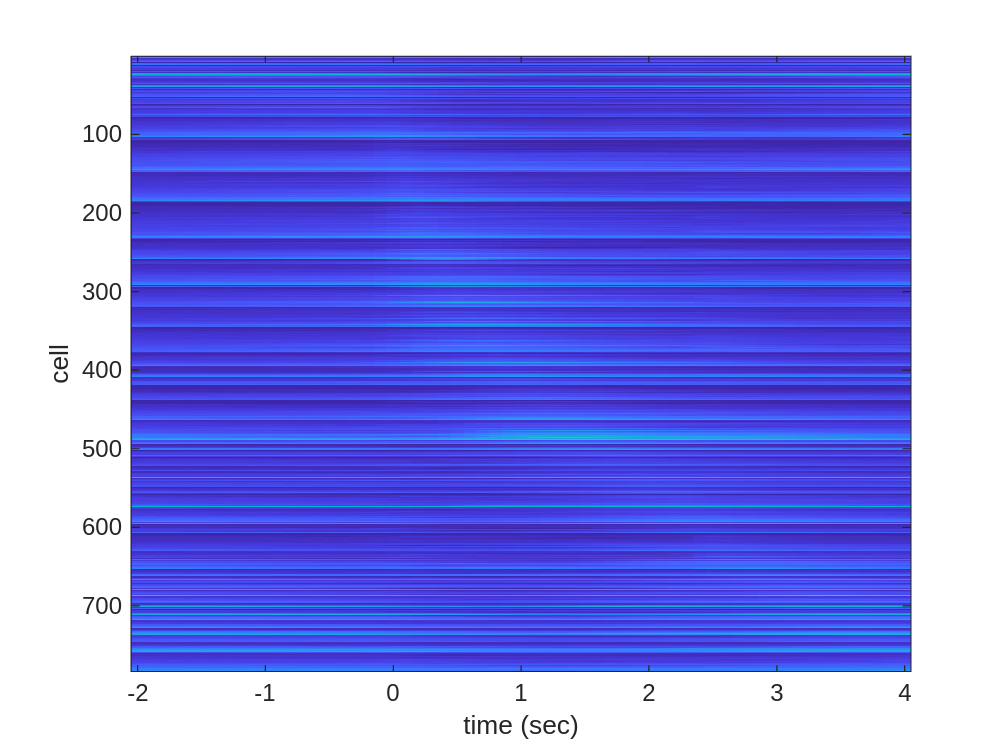

    imagesc(-before_event:0.1:after_event,1:size(trial_end_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_end_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = position_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     4.5101    4.4686    4.3983    4.3484    4.2627    4.0187    3.8771    3.8450    3.7153    3.5425    3.6074    3.5516    3.5558    3.4292    3.3644    3.3663    3.4093    3.3706    3.3316    3.2044    3.4147    3.4158    3.4847    3.5818    3.5235    3.6066    3.6058    3.7943    3.8122    3.8096    3.8963    3.8532    3.6626    3.6497    3.6903    3.7263    3.6364    3.5987    3.6710    3.4871    3.6531    3.5262    3.4542    3.5347    3.6099    3.5347    3.5936    3.5388    3.5120    3.5288
   17.3510   17.2479   16.9303   16.6275   15.3981   14.7572   13.8860   12.8039   12.0792   11.3562   10.7775    9.9945    9.4701    9.1890    8.7700    8.4467    7.7609    7.6556    7.5852    7.2094    6.8201    7.0176    7.0881    6.4498    6.3309    6.4292    6.2795    6.5497    6.8967    6.6454    7.2823    7.6473    7.8035    8.4097    8.9224    9.1081    9.4585    9.2231    9.1982    9.1433    9.3038    9.8599    9.8055    9.9235    9.9233   10.6328   11.3068   11.5521   12.1695 

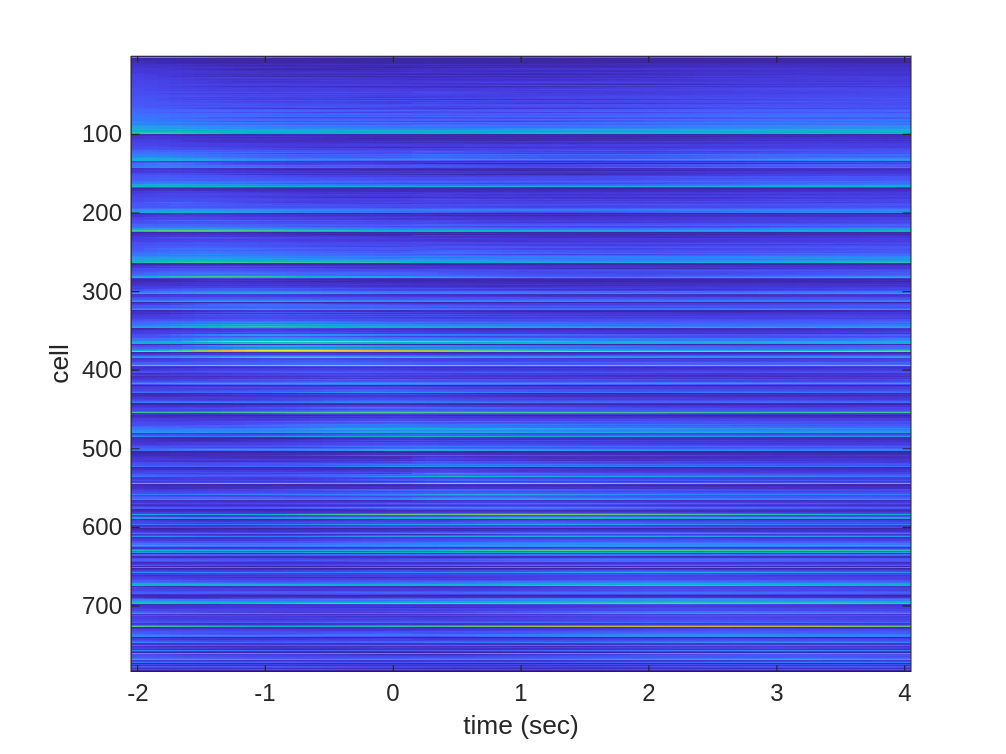

    imagesc(-before_event:0.1:after_event,1:size(position_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_position_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.3802    1.1108    1.1004    1.0995    1.0012    1.0665    1.1739    1.1728    1.2329    1.0604    1.2064    1.0702    1.0510    1.0137    1.0032    1.0630    0.8074    0.8410    0.4775    0.5922    0.7528    0.4935    0.4599    0.3954    0.3351    0.2400    0.0438    0.0815   -0.0059   -0.0673   -0.0442    0.0820    0.1034    0.0551    0.1152    0.0108    0.0059    0.0759    0.1115    0.2499    0.2647    0.3003    0.3941    0.4438    0.4376    0.5775    0.4867    0.3693    0.5822    0.6495
    3.9720    3.8481    3.8670    3.8132    3.6176    3.4942    3.4758    3.4289    3.5714    3.5352    3.5507    3.4227    3.5068    3.4590    3.3271    3.2009    3.0363    2.9593    2.7897    2.8444    3.0135    2.8403    2.8587    2.9479    2.9398    2.8347    2.8731    2.7502    2.9413    3.1031    3.1662    3.1659    3.1618    3.1585    3.1015    3.0428    3.1850    3.0723    3.1367    3.1832    3.2786    3.1098    2.9188    3.1152    3.2512    3.2442    3.2586    3.4531    3.5071 

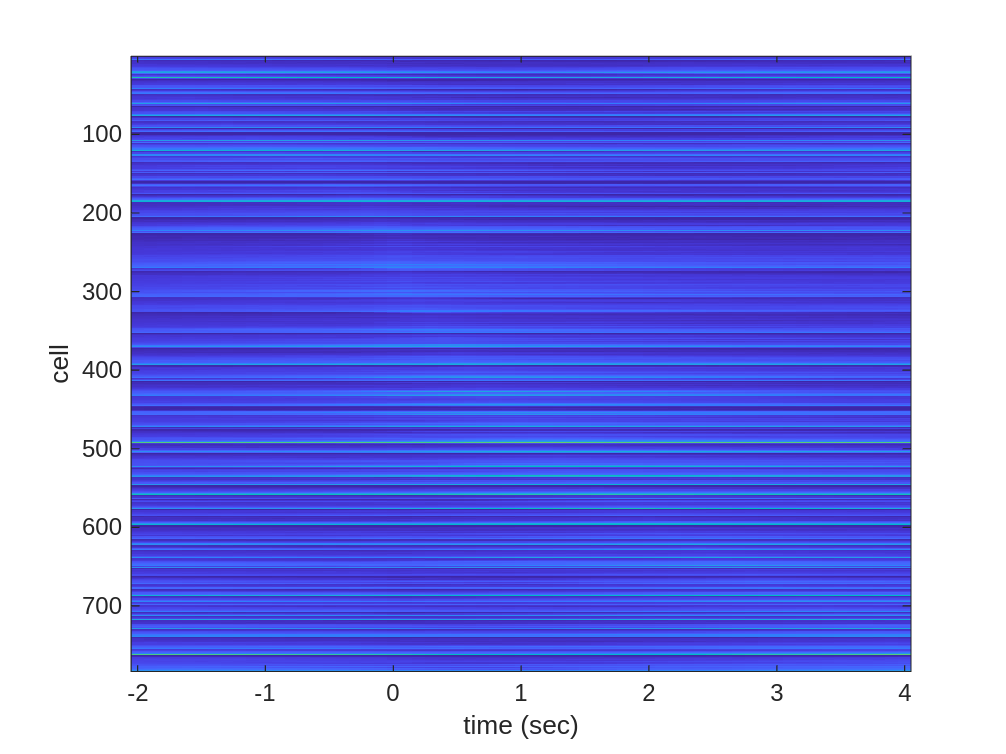

    imagesc(-before_event:0.1:after_event,1:size(force_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_force_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     2.8993    2.6236    2.8661    2.7075    2.5688    2.5533    2.7263    2.8218    2.6964    2.6005    2.4768    2.4144    2.4273    2.5229    2.6694    2.6131    2.6538    2.5517    2.5772    2.3143    2.0449    1.7921    1.7252    1.7227    1.7646    1.8642    1.8901    1.5726    1.5762    1.8367    1.7554    1.3943    1.2920    1.4014    1.3701    1.3751    1.3116    1.4560    1.6517    1.8301    2.0873    1.9580    2.0238    1.7497    1.7418    2.0697    2.2821    2.1938    2.4178    2.5906
    1.9511    2.2268    2.0435    1.9680    1.9911    2.0192    2.0317    2.0470    1.7665    1.6734    1.5882    1.7569    1.7686    1.7365    1.7952    1.8193    1.8482    1.7273    1.4776    1.5179    1.3163    1.2667    1.3114    1.6451    1.4851    1.4587    1.2672    1.0192    1.1782    1.0659    0.8133    1.0428    1.0113    1.0464    1.0846    0.9639    1.0822    1.2497    1.3713    1.3654    1.6151    1.7034    1.8673    1.8611    1.8980    1.9222    1.8586    1.9791    1.8987 

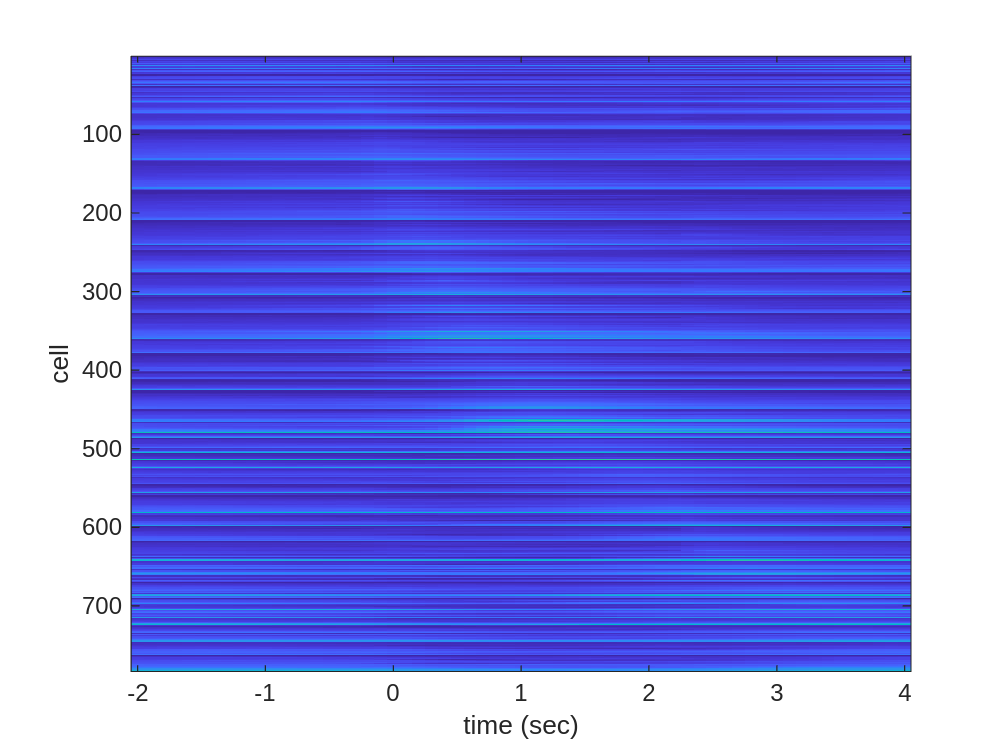

    imagesc(-before_event:0.1:after_event,1:size(reward_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_reward_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

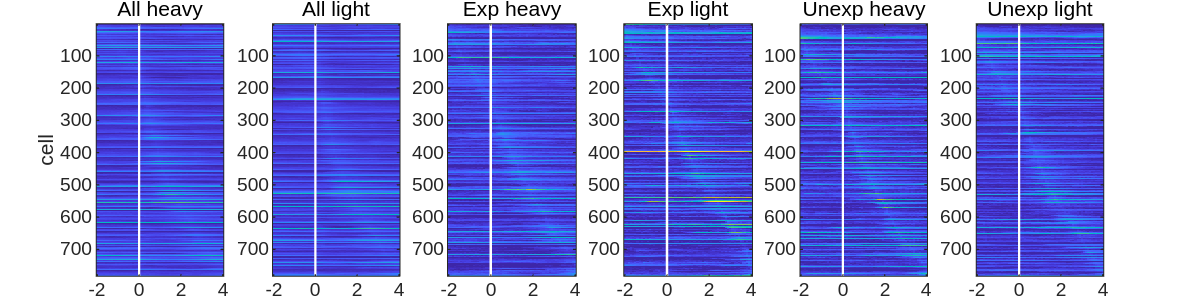

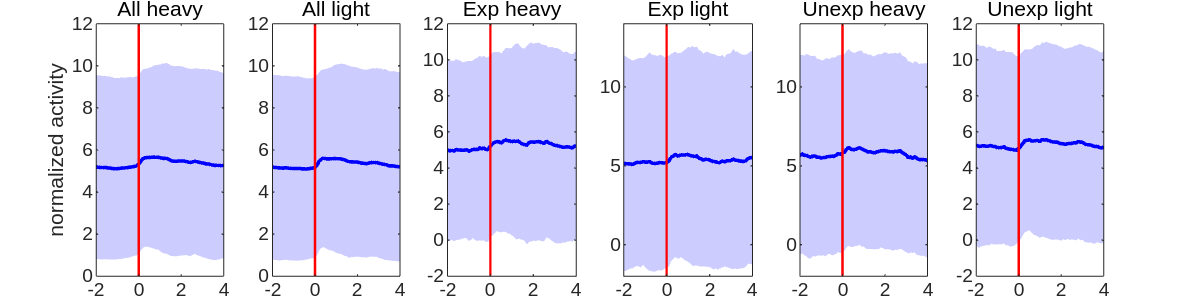

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_actss_ordered{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_actss_ordered{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;
    end
        
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_actss_ordered{i};
        data = data(~any(isnan(data), 2), :);

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);
        x = -before_event:0.1:after_event;
      
        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % xlim = [-2,4]
        % x=0に赤い縦線をプロット       
        % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0
            ylim([-1 1]);  
        end
    end
        
        filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_eta_activity.png'];
        saveas(gcf,filename);
    % close all;
end

% write eta code by categrizing neurons by layers
if categorize == 'layer'
    layer23_cells    = cell(1,length(Animal));
    layer5_cells   = cell(1,length(Animal));
    trial_start_act_layer23_cells    = cell(1,length(Animal));
    trial_start_act_layer5_cells    = cell(1,length(Animal));
    trial_end_act_layer23_cells    = cell(1,length(Animal));
    trial_end_act_layer5_cells    = cell(1,length(Animal));
    position_act_layer23_cells    = cell(1,length(Animal));
    position_act_layer5_cells    = cell(1,length(Animal));
    force_act_layer23_cells    = cell(1,length(Animal));
    force_act_layer5_cells    = cell(1,length(Animal));
    reward_act_layer23_cells    = cell(1,length(Animal));
    reward_act_layer5_cells    = cell(1,length(Animal));
    for i_animal = 1:length(Animal)
        layer23_cells{i_animal} = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 1));
        layer5_cells{i_animal}  = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 0));
        
        startAreas = cat(2,start_I{i_animal},pointAreas{i_animal});
        startAreas = sortrows(startAreas);
        startAreas(:,1) = [];
        trial_start_act_layer23_cells{i_animal} = trial_start_act_multi_animals{i_animal}(find(startAreas == 1),:);
        trial_start_act_layer5_cells{i_animal}  = trial_start_act_multi_animals{i_animal}(find(startAreas == 0),:);
        
        endAreas = cat(2,end_I{i_animal},pointAreas{i_animal});
        endAreas = sortrows(endAreas);
        endAreas(:,1) = [];
        trial_end_act_layer23_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 1),:);
        trial_end_act_layer5_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 0),:);
        
        posAreas = cat(2,pos_I{i_animal},pointAreas{i_animal});
        posAreas = sortrows(posAreas);
        posAreas(:,1) = [];
        position_act_layer23_cells{i_animal} = position_act_multi_animals{i_animal}(find(posAreas == 1),:);
        position_act_layer5_cells{i_animal}  = position_act_multi_animals{i_animal}(find(posAreas == 0),:);
        
        forceAreas = cat(2,force_I{i_animal},pointAreas{i_animal});
        forceAreas = sortrows(forceAreas);
        forceAreas(:,1) = [];
        force_act_layer23_cells{i_animal} = force_act_multi_animals{i_animal}(find(forceAreas == 1),:);
        force_act_layer5_cells{i_animal}  = force_act_multi_animals{i_animal}(find(forceAreas == 0),:);
        
        rewardAreas = cat(2,reward_I{i_animal},pointAreas{i_animal});
        rewardAreas = sortrows(rewardAreas);
        rewardAreas(:,1) = [];
        reward_act_layer23_cells{i_animal} = reward_act_multi_animals{i_animal}(find(rewardAreas == 1),:);
        reward_act_layer5_cells{i_animal}  = reward_act_multi_animals{i_animal}(find(rewardAreas == 0),:);
    end
end

% if categorize == 'layer'
%     trial_start_act_layer23_conc = trial_start_act_layer23_cells{1};
%     trial_end_act_layer23_conc   = trial_end_act_layer23_cells{1};
%     position_act_layer23_conc    = position_act_layer23_cells{1};
%     force_act_layer23_conc       = force_act_layer23_cells{1};
%     reward_act_layer23_conc      = reward_act_layer23_cells{1};
%     trial_start_act_layer5_conc = trial_start_act_layer5_cells{1};
%     trial_end_act_layer5_conc   = trial_end_act_layer5_cells{1};
%     position_act_layer5_conc    = position_act_layer5_cells{1};
%     force_act_layer5_conc       = force_act_layer5_cells{1};
%     reward_act_layer5_conc      = reward_act_layer5_cells{1};
%     for i_animal = 2:length(Animal)
%         trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%         trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%         position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%         force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%         reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%         trial_start_act_layer23_conc = vertcat(trial_start_act_layer23_conc, trial_start_act_layer23_cells{i_animal});
%         trial_end_act_layer23_conc   = vertcat(trial_end_act_layer23_conc, trial_end_act_layer23_cells{i_animal});
%         position_act_layer23_conc    = vertcat(position_act_layer23_conc, position_act_layer23_cells{i_animal});
%         force_act_layer23_conc       = vertcat(force_act_layer23_conc, force_act_layer23_cells{i_animal});
%         reward_act_layer23_conc      = vertcat(reward_act_layer23_conc, reward_act_layer23_cells{i_animal});
%         trial_start_act_layer5_conc = vertcat(trial_start_act_layer5_conc, trial_start_act_layer5_cells{i_animal});
%         trial_end_act_layer5_conc   = vertcat(trial_end_act_layer5_conc, trial_end_act_layer5_cells{i_animal});
%         position_act_layer5_conc    = vertcat(position_act_layer5_conc, position_act_layer5_cells{i_animal});
%         force_act_layer5_conc       = vertcat(force_act_layer5_conc, force_act_layer5_cells{i_animal});
%         reward_act_layer5_conc      = vertcat(reward_act_layer5_conc, reward_act_layer5_cells{i_animal});
%     end
% end

% plot layer23 neural activity
% plot neural activity heatmap
if categorize == 'layer'
    climit = [0 50]
    figure
    set(gcf,'color','w');
    for i = 1:length(Animal) 
        subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
        clims = climit;
        image = transpose(layer23_cells{i})
    %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(0:0.1:(size(layer23_cells{i},1)-1)/10,1:size(layer23_cells{i},2),image,clims);
    %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
        ylabel('cell');
        xlabel('time (sec)');
    end
    
    filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_layer23_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

climit =      0    50


image =    -0.6073    1.6376   -2.4845   -1.5848    1.8622    4.9144    3.1201    3.5788    0.9562    2.9114    0.4964    1.1528   -0.3380   -0.7149    0.4481   -0.9353    0.6581   -1.6271   -0.1410   -2.1163    1.2623   -1.1300   -0.4994   -3.3215   -0.0733    1.0036    2.6216   -0.1290   -1.7852   -0.3687   -1.3307   -3.0319   -0.6208   -0.0261   -1.5677    2.0740    6.3624    7.5583    7.1203    5.8585    5.7472    3.4943    6.5106    4.0676    3.3105    3.9170    4.0927    2.7182    2.5221    0.2699
   19.1943   19.8500   22.4008   22.4288   20.5780   21.9792   18.9960   21.1465   19.9771   20.4739   18.3122   18.6879   16.8225   15.6664   14.7821   15.8490   14.6527   16.6201   15.2203   15.8523   14.3803   12.9322   13.3999   13.3752   14.5306   12.6714   14.1009   13.9035   13.5600   12.6589   11.2215   13.2469   13.2902   11.9181   12.4750   12.6265   10.3698   14.8736   11.9484   12.8196   12.9980   12.4605   12.0690   10.0481   13.1270   12.0987    9.1243    8.3013    7.7077 

image =     5.5312    3.4061    2.9009    6.6334    4.7557    3.6974    0.5103    3.1172    2.8729    0.7352    1.3117    1.1335    0.1923   -0.6808    0.9804    2.9730    3.5766    2.5767    1.7200    0.9566   -0.1628    1.3906    6.1256    3.7214    3.6420    1.4800    1.2108    2.8291    2.6669    2.8943    3.5801    3.4254    4.6225    5.0405    5.6808    4.4681    2.4756    3.2436    1.8539   -0.2694   -0.1438   -0.4340    2.2052    1.8069    0.2623   -0.1483   -1.3185   -0.2208    0.3140   -0.6083
   19.8261   18.1194   16.1916   18.3759   17.6773   13.7738   15.1813   14.2584   14.0020   14.1176   12.1647   14.4782   14.7042   12.1814   10.4304   11.2419   14.0235   11.5521    9.6227    7.2824    7.3874    8.6469    7.1525    6.1847    7.2883    5.5563    5.1347    4.5699    5.1464    3.4691    2.9129    3.2296    4.0338    3.3628    3.8528    3.7056    6.0278    7.9587    4.3560    7.1440    9.6694    8.3662    8.0975    8.5942   11.1462   11.4419   10.2498    9.7637    9.6539 

image =     7.9345    6.2008    6.9143    8.8605    7.6817    6.8502    7.6451    8.6332    8.4813    5.9377    6.9494    5.9340    5.8091    4.3933    4.6818    6.7352    6.1504    4.3954    5.4079    3.0535    4.2303    2.1573    0.1623    3.1129    2.8901    1.0214   -0.0591    1.6897    2.1838    2.2406    2.3460    1.6887    1.8817    1.9929   -0.7284    0.5944    0.0934    1.3391    1.8089    1.6875    0.7023    1.3001    1.4706    1.6602    2.2232    2.0138    1.0648   -0.9894    2.2818    2.9606
    6.1400    7.3509    5.9760    7.1311    5.7752    4.6622    6.2430    5.9767    8.7952    4.8363    6.6129    5.8958    4.8085    5.3792    7.0395    6.5966    5.6514    6.4254    8.0102    7.4224    7.1891    5.1918    4.7682    6.0772    6.8662    4.8172    3.8148    3.5060    5.8741    5.1571    4.7502    3.9226    3.4027    4.1100    2.0475    4.6232    5.5920    7.0605    6.0660    4.9862    6.6022    6.3599    5.0770    4.3837    5.9938    5.7855    1.9557   -0.4009    3.6990 

image =    21.8092   23.2145   22.1190   22.0802   19.5605   16.3138   15.3159   12.6924   14.6209   12.1100   10.2625    9.2859   12.0909   14.4480   17.1436   15.3774   15.2941   13.4570   12.9971   12.2713    8.0813    9.3622    7.3539    7.0766    7.5430    7.9500    5.9018    5.8587    6.5252    6.2986    4.2139    2.8871    2.9891    3.3117    3.5906    3.2437    1.7721    1.9786    1.1832    0.8493    1.7115    1.2972    2.4261    2.2250    2.6884    2.3692    3.2224    3.1211    3.0347    2.2784
   22.2124   25.0122   22.9286   21.8366   21.8349   20.1584   21.5806   21.3999   21.2707   23.1485   23.1264   19.5735   18.9128   16.8659   20.0310   18.8777   21.0908   18.1422   17.9673   16.4212   14.8761   14.5920   15.0731   15.9313   14.4443   12.6144   13.1221   13.6082   16.8686   17.8079   14.5184   16.7333   15.9460   16.7658   15.1483   14.5550   15.1820   14.8619   14.0060   13.4733   10.7768   11.1646   10.8854    8.6502    9.7806    8.4206    8.9685    9.9513   10.3251 

image =    23.0793   22.3205   22.2461   20.6899   21.4158   19.1922   20.5173   21.0884   20.3110   18.7052   22.2946   24.8154   28.1607   28.9147   29.3508   30.2013   28.7444   30.6928   30.6061   30.8241   24.9523   24.4026   27.4787   28.6038   28.7437   33.3755   33.8426   38.7569   38.1263   34.4079   31.0859   35.3856   33.2317   31.4520   30.5467   27.7831   26.7482   27.9398   25.0261   26.8085   26.3707   23.9034   22.4893   22.7750   19.7079   20.4835   21.4386   21.4136   21.5165   19.6281
    4.3093    2.2636    1.1777   -0.7565    0.8840   -3.2646    0.7608   -0.7572   -4.7008   -4.9494   -5.2806   -3.2847   -6.6857   -7.8669   -9.3745   -9.2718   -7.3947   -6.1733   -6.3995   -3.9264   -1.8076   -0.0834    5.0410    6.9194   13.2162   12.8940   13.9587   10.3299    8.0801    4.2909    5.6154    4.1874    3.9081    0.8863   -1.1546    0.8193   -0.0179    0.2933    0.4699    3.4543    3.9142    4.5274    0.4344    0.8669    3.9957    2.7859    1.7144    3.7309    3.6999 

image =    16.6359   15.3622   11.5248   12.0197   12.5889   14.8708   17.0416   15.6458   17.1734   16.5299   17.2303   16.7972   15.3090   20.3449   22.2428   23.0813   26.4944   26.1694   27.5845   27.6525   28.1721   28.9071   24.7963   23.5643   24.0778   22.2227   18.7885   18.0805   17.9059   19.3299   18.2907   17.2233   17.6659   19.5968   18.7525   16.6079   12.2490   11.5227   12.4255   11.0991   10.8123   12.1535   11.1091    9.8386   11.0708   12.8400   10.3846    9.8001   10.0718    9.8328
   14.6035   13.1625   10.6420   11.1770    8.8750    8.7531   11.7420   10.4485    9.5412   10.0518   11.4514   10.0134   11.3514   11.8281    9.8274    8.2649    9.6671    8.3586    7.9546    7.8683    8.1341    7.4824    5.5235    6.4486    6.4440    6.3862    8.2431    6.9832    6.4025    6.2569    5.7252    7.7696    7.4292    9.7215   11.1325   12.7149    9.4132   10.3625   12.3676   13.1366   11.5932   11.0286   11.2964    9.6155    9.4268    9.7788   10.8238    8.4534    8.5844 

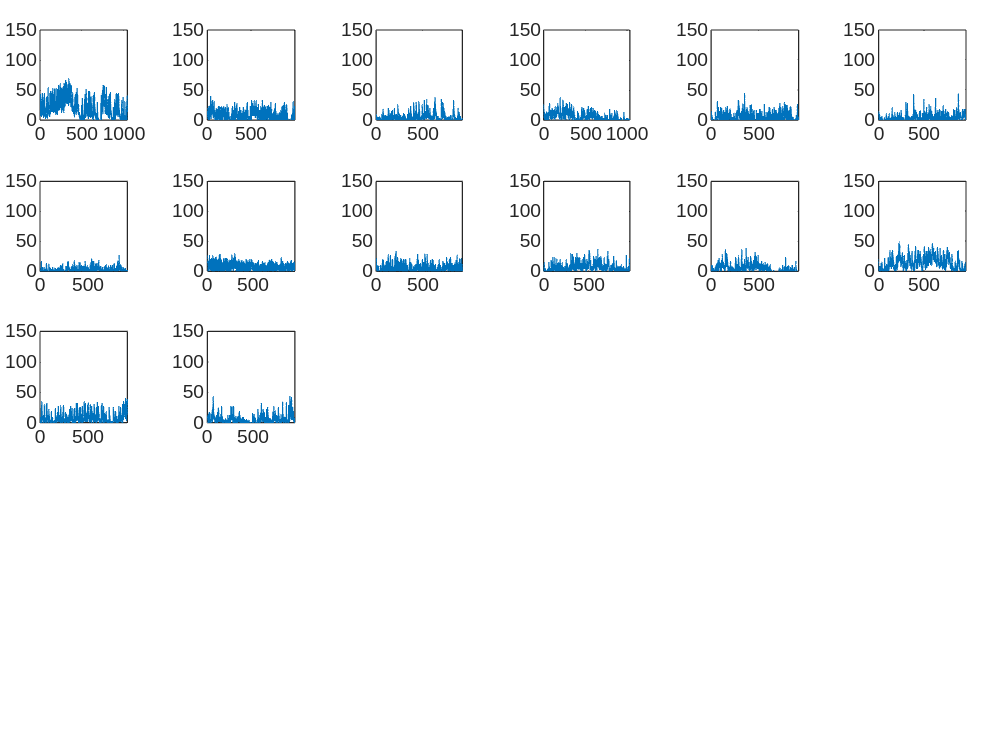

if categorize == 'layer'
    addpath([working_directory 'Utility' filesep 'Subaxis']);
    example_num = 5;
    display_start = 1; %113;
    ylimit=[0 150];
    figure
    for j = 1:length(Animal)
        for i = 1:example_num
            subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
            b = plot(0:0.1:(size(layer23_cells{j},1)-1)/10,layer23_cells{j}(:,display_start+i));
        %     title([brain_roi_name(i)], 'FontSize',6);
            ylim(ylimit); 
            xlim([0 (size(layer23_cells{j},1)-1)/10]);
        %     ylabel('neural activity');
        %     xlabel('time (sec)')
        end
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_layer23_exmple_activity_traces.png'];
    saveas(gcf,filename);
    end
end

% plot layer5 neural activity
% plot neural activity heatmap
if categorize == 'layer'
    climit = [0 50];
    figure
    set(gcf,'color','w');
    for i = 1:length(Animal) 
        subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
        clims = climit;
        image = transpose(layer5_cells{i})
    %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(0:0.1:(size(layer5_cells{i},1)-1)/10,1:size(layer5_cells{i},2),image,clims);
    %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
        ylabel('cell');
        xlabel('time (sec)')
    end
    
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_layer5_activity_heatmap.png'];
    saveas(gcf,filename);
    close all;
end

image =     3.5341    2.8302    3.5223    4.5703    2.9494    1.6509    3.6796    2.4597    2.5524    2.6402    3.1517    2.8023    3.8732    2.9356    4.1216    3.4461    6.5523    4.0794    4.4293    5.6014    5.1137    6.0465    4.1704    6.2402    6.3832    4.7340    5.0599    6.1110    4.9632    5.2415    7.8249    7.6952    7.6395    8.9862    5.7965    6.0707    5.0877    6.0095    6.4888    7.8661    5.6828    4.5485    5.6945    5.5344    5.6597    7.0883    6.8895    7.7589    6.5579    8.0413
    8.5480    7.0851    8.4641    7.4308    8.9080    9.4726    8.5021    7.7170    8.4345   10.2685    8.2568    7.8866    6.6524    7.1368    5.0171    6.5243    6.1496    5.7513    6.9307    4.1326    6.8369    7.3973    6.2105    4.6963    5.1637    5.4389    4.3257    6.3393    5.3141    6.2950    3.6277    4.0226    4.8387    6.0990    4.4562    3.7639    3.9874    4.4045    5.6667    3.7390    6.1141    6.0474    3.4107    3.9374    4.1538    3.6898    4.2480    2.6604    4.5364 

image =     0.8059    1.3809   -1.8984   -1.4222   -1.0689    0.3222   -1.1104    0.4679    2.8398    1.0797    0.5992    0.5782   -0.5719   -0.8152   -1.6802   -2.1442   -1.0454   -1.1633   -1.1730   -2.2032   -0.4721   -0.0796   -1.1979    0.4152   -1.5169    0.4042   -0.2542    0.8733   -1.3591   -1.5090   -1.7636   -0.9816   -3.3186   -2.2770   -2.0884   -1.5102   -1.4939   -0.9538   -0.2929   -0.7176    0.7152   -0.6368   -0.6505   -1.4008   -1.1748    0.2227   -1.4427   -2.2086   -3.2206   -4.5499
    7.9956    5.6744    5.7120    5.2805    7.3446    6.0690    4.9843    3.3899    5.8380    6.3230    6.1356    6.4926    5.1818    5.2143    3.6263    4.0573    4.5166    3.3452    1.9122    1.5340    0.7467    3.2301    5.1429    4.2084    2.8414    2.8939    0.7704   -0.5839    0.7699    1.1597    2.1426    3.2407    3.7340    3.6255    1.5907    2.6223    3.1318    2.3264    1.0237    1.8510    0.3013    2.4069    1.3366    1.1148   -0.2445   -0.6812   -0.1863    0.5340    2.2739 

image =    30.5938   34.4939   33.8638   34.6602   34.0666   32.8777   31.0892   30.9577   29.5101   28.6825   27.7363   25.1396   26.7202   22.8118   25.0959   25.0152   25.0761   22.4619   21.7593   24.3249   24.3921   21.5658   20.2246   20.2481   22.0877   21.9823   20.7258   19.2207   17.5374   21.3061   15.8893   20.9271   16.9138   16.2539   19.1000   17.8280   17.9090   17.4104   20.1851   16.5848   15.6384   16.2927   14.6627   14.4960   15.1768   14.4322   13.4744   13.1810   11.5588   15.1286
    6.7873    4.6222    5.9369    6.6326    5.5271    3.7659    4.7544    4.7357    2.9020    5.7324    4.2884    3.2571    3.0594    4.8759    3.4521    2.8833    2.7988    3.8643    3.6861    2.9982    2.6133    3.6186    1.3463    2.3782    2.7806    3.0518    2.2057   -1.2099    0.1669    0.9556    1.9335    2.3491    3.4223    4.5037    2.2879    1.7966    0.7231    1.1693   -0.6694    0.5449    2.3747    0.2481    1.2633   -0.2519    0.5972    0.8695    1.5226    1.7483    0.3455 

image =    25.0810   25.3593   24.7782   22.6878   23.1461   22.0915   24.0479   20.0013   21.8335   24.1203   24.6560   25.1507   24.7741   25.0841   25.7213   22.9528   25.8093   23.7255   23.7328   22.7239   24.3924   23.1109   24.7816   22.9194   22.9623   20.1553   21.1090   21.8222   23.0632   21.9597   21.9919   23.3029   22.9453   22.3283   23.5853   22.3168   22.1593   18.9604   19.2501   20.6746   19.6959   18.6315   16.0800   17.3387   16.2292   15.5809   16.7961   18.4013   19.0271   16.3580
   16.8110   15.1292   13.1907   11.6366   10.6645   12.1270    9.5272   10.4362    9.4788    8.6546    6.0694    9.0601    8.3308    9.0487   10.2558    7.6944    9.7111   10.6760   11.5544   11.1358   12.7622    9.4015    6.6466    5.5169    6.3857    4.5759    6.8116    2.7163    2.8379    3.0241    5.7551    8.0957    5.7103    7.7429    8.1651    5.4116    6.0136    3.7150    5.6265    4.9778    4.6982    4.0703    3.6174    3.5689    4.4807    4.5456    8.1806    8.4716   10.4437 

image =    -0.1652   -0.9011    0.1338    4.3876   -0.0634   -0.4433    0.9672   -2.6393    0.1555    1.0761   -0.8530   -0.8902   -0.6955   -2.1394   -2.5512   -3.0380   -3.1582   -4.3738   -2.2623   -3.5139   -3.9194   -3.3400   -3.5008   -1.4795   -0.5261   -0.9125   -0.3066    1.6217   -1.0275   -1.7857   -3.6931   -3.2444   -2.7137   -1.9097   -2.1135   -2.1451   -3.5315   -2.3253   -1.3036   -2.3623   -2.2623   -1.5791   -4.2681   -5.1073   -5.6617   -4.1447   -6.4331   -6.3965   -5.6874   -2.2060
   11.5914    8.6092   11.3387    9.7332   10.7234   11.4795   12.6238   11.9299   10.8452    7.4151    9.1714    9.0661    9.7284    8.4053   10.7702   10.0303    9.1096    8.6364    8.3566    9.2892    9.9146   10.3922   10.7606   12.4293   11.8227   10.2162   12.6213   14.7932   15.2386   14.8030   12.3460   11.1307   11.6954   13.2912   13.9707   12.2559   12.9809   12.7026   14.0501   15.0804   12.2253   12.7432   12.6970   14.4998   12.6395   10.8508    8.9733   11.5142   12.2774 

image =    17.3794   16.0831   11.3176   13.3634   12.8779   12.2955   14.1332   16.5777   16.5017   17.4795   17.5939   15.9593   16.2093   14.3453   17.1486   12.5543   13.0087   10.5676    9.1960    8.3720    6.9655    8.5301    7.1532    9.1698   10.6126   11.6204   11.3910    8.8069    9.2269    9.4376    9.6696    8.4598    8.4715    8.7128   10.2549    8.1421    7.3064    7.2351    9.8399   11.7056    8.2647   10.1676   10.2495    9.5674    9.4556   10.0750    8.6762    8.5579    6.7824    6.5091
    1.9346    3.5102    2.7675    4.6679    2.0988    6.1173    2.3006    0.4062    1.0857    0.0118    0.4326   -2.8314    1.5012   -0.4586   -3.6657   -4.2118   -4.1720   -6.7578   -3.3060   -3.5730   -5.2870   -4.2596   -0.2509   -0.8678   -0.2761   -3.3074   -4.6285   -6.2500   -6.8243   -7.9937   -7.3530   -7.3070   -6.2211   -9.4013   -7.3958   -8.3961   -7.2168   -6.3632   -7.2753   -7.0086   -5.7867   -4.6779   -3.1925   -2.8535   -0.4999   -3.9551   -3.8669   -1.8349   -2.4602 

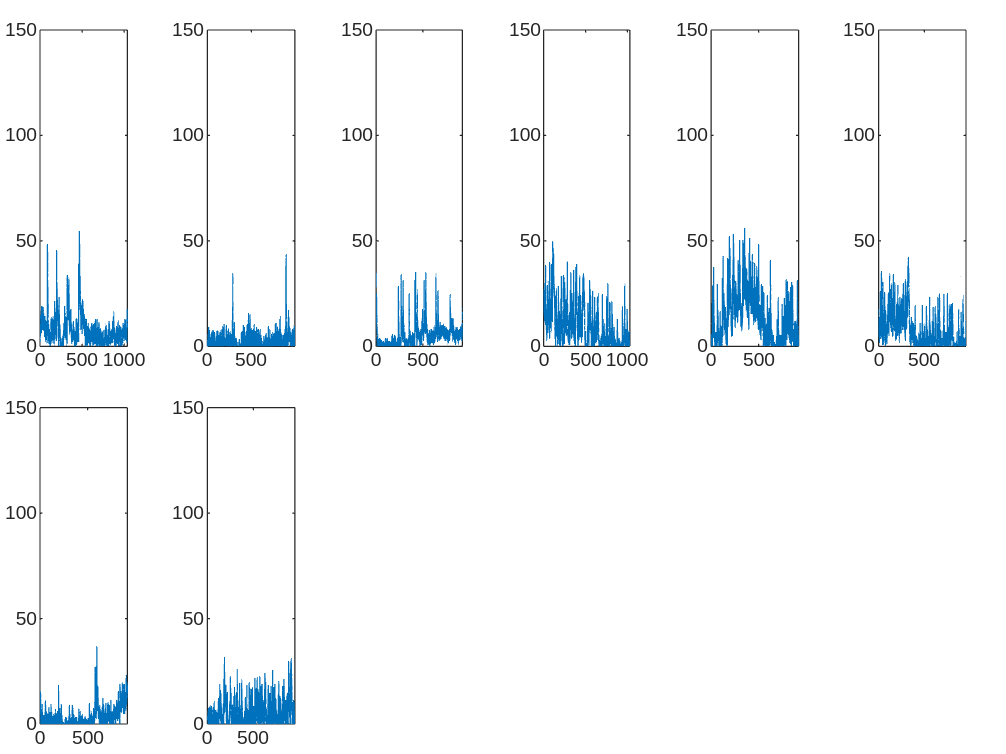

if categorize == 'layer'
    addpath([working_directory 'Utility' filesep 'Subaxis']);
    example_num = 2;
    display_start = 0; %113;
    ylimit=[0 150];
    figure
    for j = 1:length(Animal)
        for i = 1:example_num
            subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
            b = plot(0:0.1:(size(layer5_cells{j},1)-1)/10,layer5_cells{j}(:,display_start+i));
        %     title([brain_roi_name(i)], 'FontSize',6);
            ylim(ylimit); 
            xlim([0 (size(layer5_cells{j},1)-1)/10]);
        %     ylabel('neural activity');
        %     xlabel('time (sec)')
        end
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_layer5_exmple_activity_traces.png'];
    saveas(gcf,filename);
    end
end

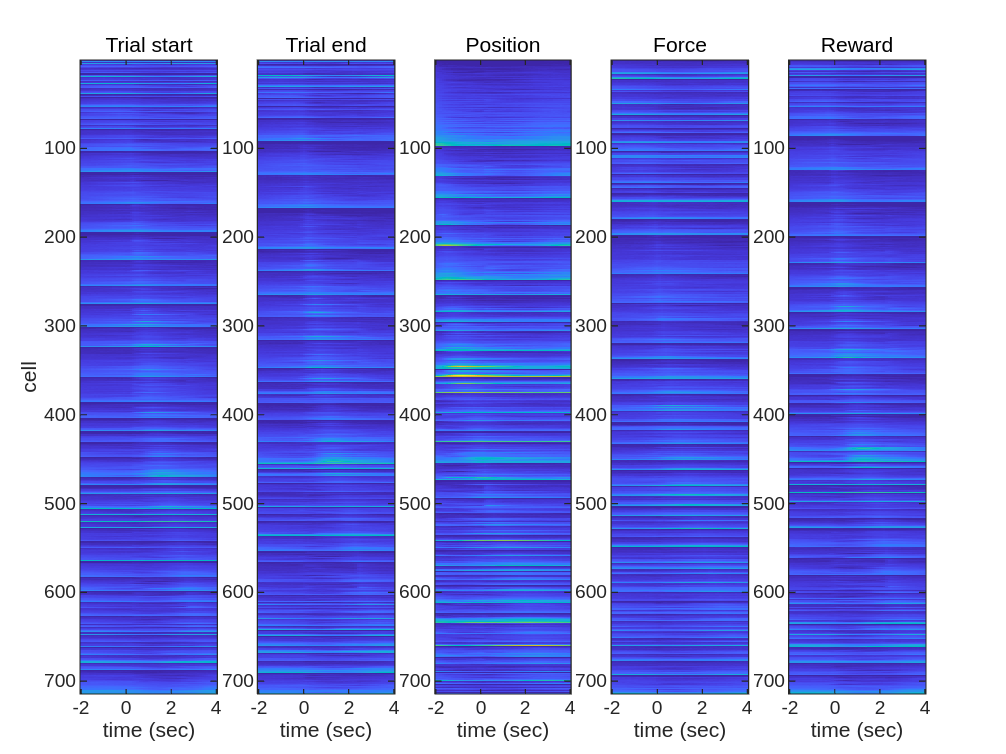

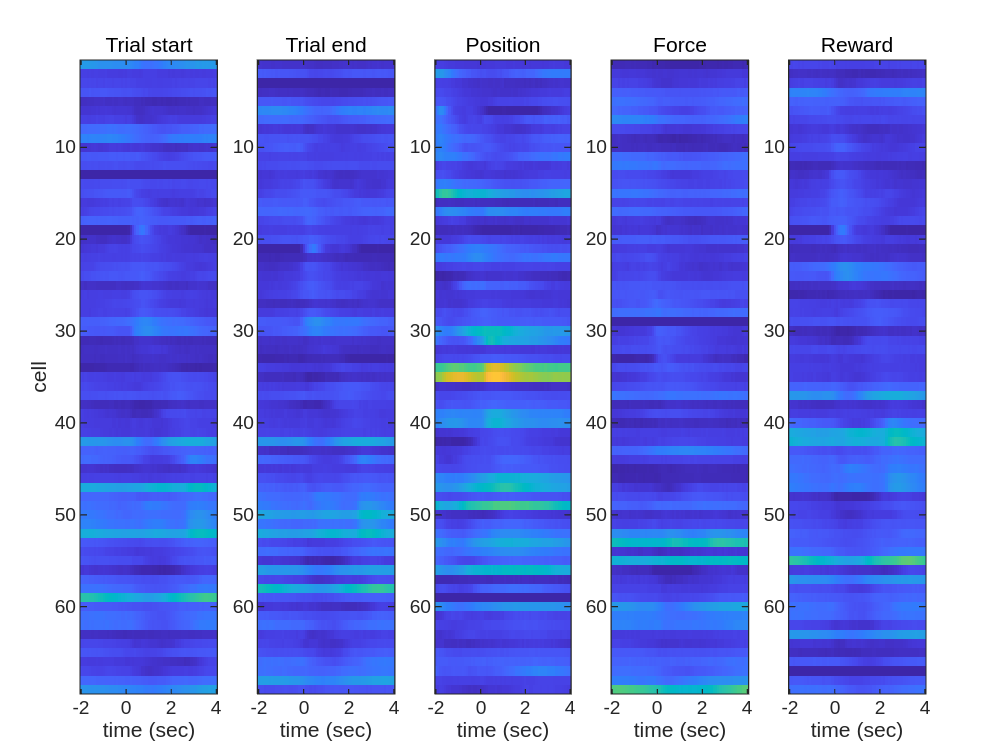

% plot layer specific eta by multiple plane figure
if categorize == 'layer'
    if norm == 1
        climit = [0 1];
    elseif norm == 2 | norm == 3 | norm == 4
        climit = [-2 2];
    % else
    %     climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_conc, trial_end_act_layer23_conc, position_act_layer23_conc, force_act_layer23_conc, reward_act_layer23_conc};
    layer5_act  = {trial_start_act_layer5_conc, trial_end_act_layer5_conc, position_act_layer5_conc, force_act_layer5_conc, reward_act_layer5_conc};
    title_list = {'Trial start', 'Trial end', 'Position', 'Force', 'Reward'};
    figure
    set(gcf,'color','w');

    for i = 1:length(layer23_act) 
        subaxis(1,length(layer23_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer23_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer23_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure
    set(gcf,'color','w');
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer5_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer5_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

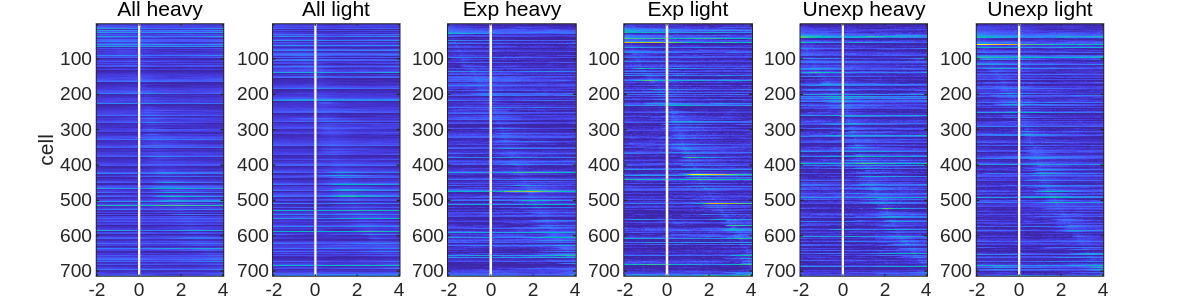

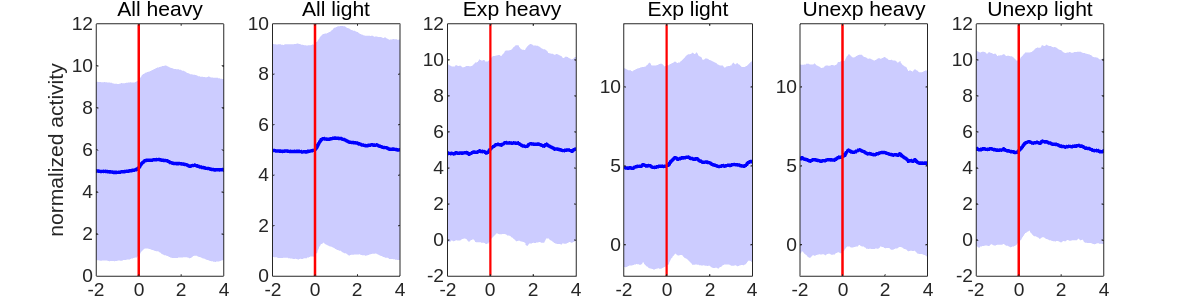

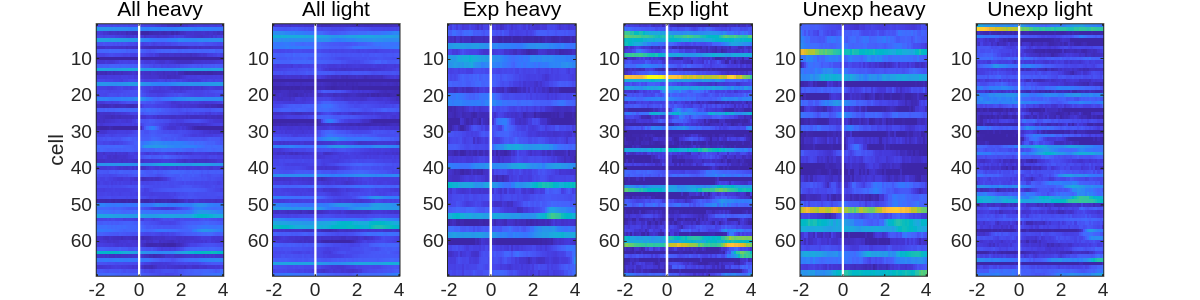

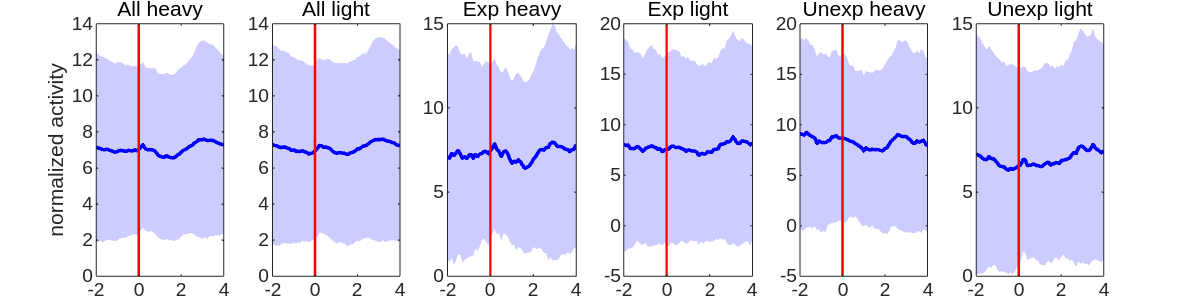

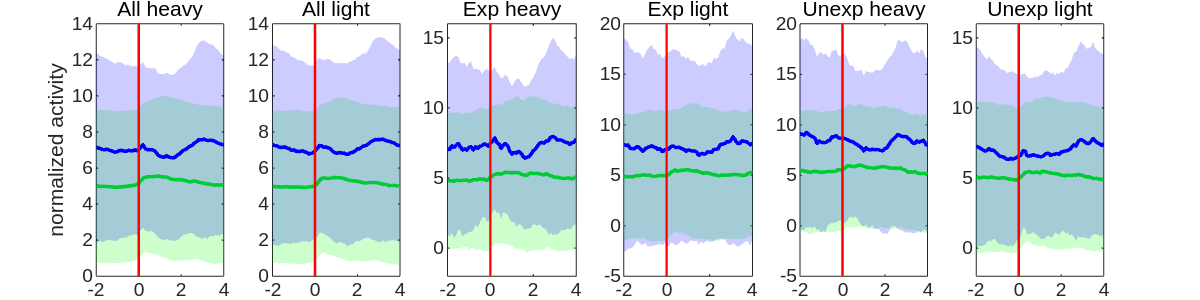

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if categorize == 'layer' & Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;           
    end
        
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer23_cells{i};
        data = data(~any(isnan(data), 2), :);

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);      
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end      
        hold off;
        axis tight;  
        if norm ~= 0
            ylim([-1 1]);  
        end      
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
        
    end
        
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);        
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;          
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer5_cells{i};
        data = data(~any(isnan(data), 2), :);

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end       
        hold off;
        axis tight;          
        if norm ~= 0
            ylim([-1 1]);  
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data23 = pull_act_layer23_cells{i};
        data23 = data23(~any(isnan(data23), 2), :);
        data5 = pull_act_layer5_cells{i};
        data5 = data5(~any(isnan(data5), 2), :);        

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        mean_values23 = mean(data23, 1);
        std_values23 = std(data23, 0, 1);        
        mean_values5 = mean(data5, 1);
        std_values5 = std(data5, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end        
        hold off;
        axis tight;  
        if norm ~= 0
            ylim([-1 1]);  
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

%TODO: make muliple dimention reduction map
% % Dimention reduction using PCA, tSNE and UMAP
% comp_pca = pca(acc_neural_activity_data);
% comp_tsne = tsne(transpose(acc_neural_activity_data));

% figure
% scatter(comp_pca(:,1),comp_pca(:,2));
% xlabel('PC1');
% ylabel('PC2');

% figure
% scatter(comp_tsne(:,1),comp_tsne(:,2));
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');

% if categorize == 'layer'
%     colorcode = pointAreas;
% end
% if categorize == 'depth'
%     colorcode = depth
% end

% % Color hidden dimention by depth of cells
% figure
% % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
% xlabel('PC1');
% ylabel('PC2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_PCA.png'];
% saveas(gcf,filename);

% figure
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); % ,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_tSNE.png'];
% saveas(gcf,filename);

% Dimention reduction of trial_start_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_start_act_conc));
comp_tsne = tsne(trial_start_act_conc);
if categorize == 'layer'
    colorcode = startAreas;
end
if categorize == 'depth'
    colorcode = startDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');

次を使用中のエラー: scatter (行 68)
色は 1 つの RGB 3 成分か、RGB 3 成分からなる m 行 3 列の行列 (散布点ごとに 1 つの色)、あるいは m 行 1 列のベクトル (散布点ごとに 1 つの値) でなければなりません。

xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_start_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_start_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_start_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_start_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of trial_end_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_end_act_conc));
comp_tsne = tsne(trial_end_act_conc);
if categorize == 'layer'
    colorcode = endAreas;
end
if categorize == 'depth'
    colorcode = endDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_end_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_end_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_end_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_end_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of position_act using PCA and tSNE 
comp_pca = pca(transpose(position_act_conc));
comp_tsne = tsne(position_act_conc);
if categorize == 'layer'
    colorcode = posAreas;
end
if categorize == 'depth'
    colorcode = posDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_position_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_position_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_position_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_position_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of force_Act using PCA and tSNE 
comp_pca = pca(transpose(force_act_conc));
comp_tsne = tsne(force_act_conc);
if categorize == 'layer'
    colorcode = forceAreas;
end
if categorize == 'depth'
    colorcode = forceDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_force_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_force_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_force_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_force_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of reward_Act using PCA and tSNE 
comp_pca = pca(transpose(reward_act_conc));
comp_tsne = tsne(reward_act_conc);
if categorize == 'layer'
    colorcode = rewardAreas;
end
if categorize == 'depth'
    colorcode = rewardDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_reward_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_reward_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_reward_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_reward_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% layer specific dimention reduced neural activity timecourse

% layer23_act = [trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells];
% layer5_act  = [trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells];

% Dimention reduction of reward_Act using PCA and tSNE 

% Color hidden dimention by depth of cells
autumn = colormap('autumn');
winter = colormap('winter');
scaled_autumn_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(autumn,1)),autumn, 1:size(layer23_act_conc{1},2));
scaled_winter_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(winter,1)),winter, 1:size(layer23_act_conc{1},2));
figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_pca = pca(layer23_act_conc{i});
    layer5_comp_pca = pca(layer5_act_conc{i});
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('PC2');
    if i == 5
        xlabel('PC1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
    colormap(flipud(colormap));
    % colorbar('Direction','reverse');
    % caxis([0 1100]);
end
xlabel('PC1');
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_eta_PCA_timecourse.png'];
saveas(gcf,filename);

figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_tsne = tsne(transpose(layer23_act_conc{i}));
    layer5_comp_tsne = tsne(transpose(layer5_act_conc{i}));
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_tsne(:,1),layer23_comp_tsne(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('t-SNE coordinate2');
    if i == 5
        xlabel('t-SNE coordinate1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_tsne(:,1),layer5_comp_tsne(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
%     xlabel('t-SNE coordinate1');
%     ylabel('t-SNE coordinate2');
    colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
end
xlabel('t-SNE coordinate1');
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_eta_tSNE_timecourse.png'];
saveas(gcf,filename);


% % Clustering neural activity
% [idx,C] = kmeans(transpose(acc_neural_property_data),3);
% x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
% x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)];
% idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');
% 
% figure;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% colormap(flipud(colormap));
% colorbar('Direction','reverse');
% caxis([0 1100]);
% hold off;

% Example usage
% points = [1, 2; 3, 4; 5, 6]; % Nx2 array of points to classify
% linePoints = [0, 0; 2, 2; 3, 1]; % 3x2 array of points defining the first line
% 
% pointAreas = classifyPoints(points, linePoints);
% disp(pointAreas);

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (low:0 or high:1)

    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end